# **OFDM Transmitter with Coding **

## Initialize Transmitter Parameters

[sysParam,txParam,trBlk] = helperOFDMSetParamsSDR(OFDMParams,dataParams);
sampleRate               = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal
ofdmTx                   = helperGetRadioParams(sysParam,sampleRate,centerFrequency,gain);

% Get the radio transmitter and spectrum analyzer system object system object for the user to visualize the transmitted waveform.
[radio,spectrumAnalyze] = helperGetRadioTxObj(ofdmTx);

## Generate Transmitter Waveform 

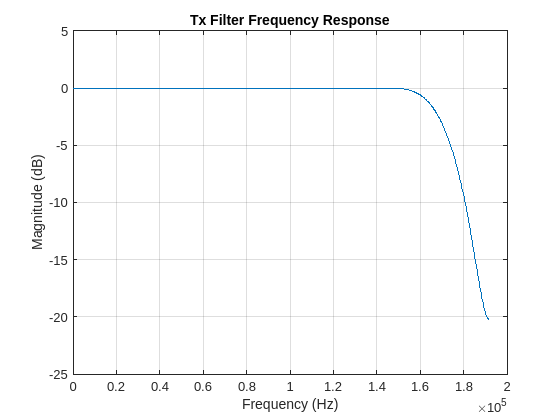

% Initialize transmitter
txObj = helperOFDMTxInit(sysParam);
tunderrun = 0; % Initialize count for underruns

% A known payload is generated in the function helperOFDMSetParams with
% respect to the calculated trBlkSize
% Store data bits for BER calculations

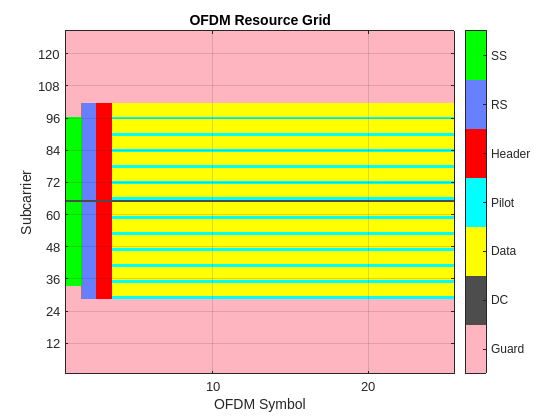

txParam.txDataBits = trBlk;
[txOut,txGrid,txDiagnostics] = helperOFDMTx(txParam,sysParam,txObj);

% Display the grid if verbosity flag is enabled
if dataParams.verbosity
    helperOFDMPlotResourceGrid(txGrid,sysParam);
end

% Repeat the data in a buffer for PLUTO radio to make sure there are less
% underruns. The receiver decodes only one frame from where the first
% synchroization signal is received
txOutSize = length(txOut);

if txOutSize < 48000
    frameCnt = ceil(48000/txOutSize);
    txWaveform = zeros(txOutSize*frameCnt,1);
    for i = 1:frameCnt
        txWaveform(txOutSize*(i-1)+1:i*txOutSize) = txOut;
    end
else
    txWaveform = txOut;
end

if dataParams.enableScopes
    spectrumAnalyze(txOut);
end

## Transmit Over Radio

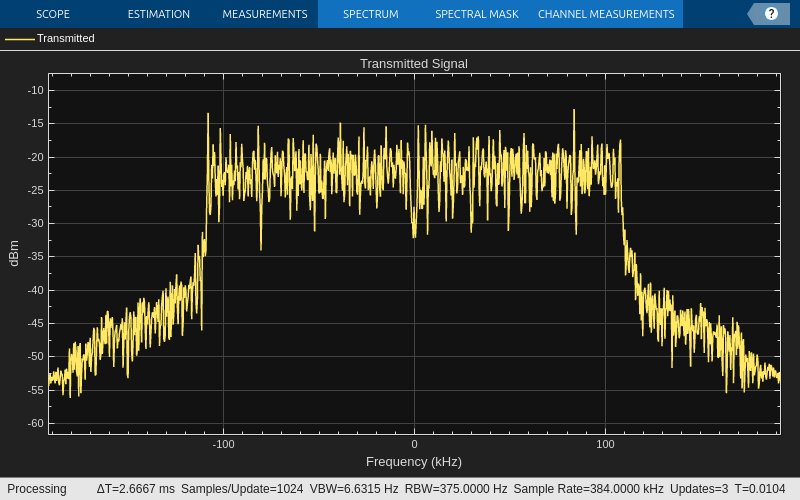

for frameNum = 1:sysParam.numFrames+1
    underrun = radio(txWaveform);
    tunderrun = tunderrun + underrun;  % Total underruns
end
% Clean up the radio System object

release(radio);

## Establishing connection to hardware. This process can take several seconds.
